# Simulate Single-Cell for A Long Time: For Statistics

## first, setup connctivity map

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

历时 24.585124 秒。



C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

历时 9.062228 秒。



C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

历时 7.720795 秒。



C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

历时 2.804540 秒。


% mVEpre = mVE; mVIpre = mVI;
% f_EnI0 = MeanFieldEst_BkGd(C_EE,C_EI,C_IE,C_II,...
%                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
%                                    lambda_E,S_Elgn,rE_amb,S_amb,...
%                                    lambda_I,S_Ilgn,rI_amb,...
%                                    gL_E,gL_I,Ve,Vi,mVE,mVI);


## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 0.059; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; S_Ilgn = 0.084; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 
rE_amb = 0.72; rI_amb = 0.36;
T = 2000; sampleT = 2; SimulationT = 1000;

% Replace S_EI by testing values
S_EItest = 0.054:0.001:0.068;

## Run single cell simulation for long time...

% Get connectivity for the center HC
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

% Take averaged number of input neurons 
% NOTE! Only picking up the middle part
N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

f_EnI_Single = [3.5; 11];

Run Single Cell Simulation

tic
ExpoType = 'All';
SimuTime = 100*1e3; % in ms
TimeGrid = 0.1;
t_grid = 0:TimeGrid:SimuTime;
[VE_Single,SpE_Single] = MEanFieldEst_SingleCell('e', ExpoType, SimuTime, TimeGrid,...
                                         f_EnI_Single, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                         lambda_E,S_Elgn,rE_amb,S_amb,...
                                         lambda_I,S_Ilgn,rI_amb,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi);
[VI_Single,SpI_Single] = MEanFieldEst_SingleCell('i', ExpoType, SimuTime, TimeGrid,...
                                         f_EnI_Single, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                         lambda_E,S_Elgn,rE_amb,S_amb,...
                                         lambda_I,S_Ilgn,rI_amb,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi);
toc

历时 0.446499 秒。


## Single Neuron Data Processing

Dt = 0.002*1e3;
TSample_grid = 0:Dt:SimuTime;
ScaleNum = floor(Dt/TimeGrid);
% Sample and average Vs by lengths
VE_Sample = nanmean(reshape(VE_Single(1:ScaleNum*(length(TSample_grid)-1)),ScaleNum,length(TSample_grid)-1));
VI_Sample = nanmean(reshape(VE_Single(1:ScaleNum*(length(TSample_grid)-1)),ScaleNum,length(TSample_grid)-1));
SpE_Sample = zeros(1,length(TSample_grid)-1);
SpI_Sample = zeros(1,length(TSample_grid)-1);
for TSampleInd = 1:length(TSample_grid)-1
    SpE_Sample(TSampleInd)  = sum(SpE_Single >= TSample_grid(TSampleInd) & SpE_Single< TSample_grid(TSampleInd+1)) /(Dt/1e3);
    SpI_Sample(TSampleInd)  = sum(SpI_Single >= TSample_grid(TSampleInd) & SpI_Single< TSample_grid(TSampleInd+1)) /(Dt/1e3);
end
var(VE_Sample)

ans = NaN

var(SpE_Sample)

ans = 1.6204e+03

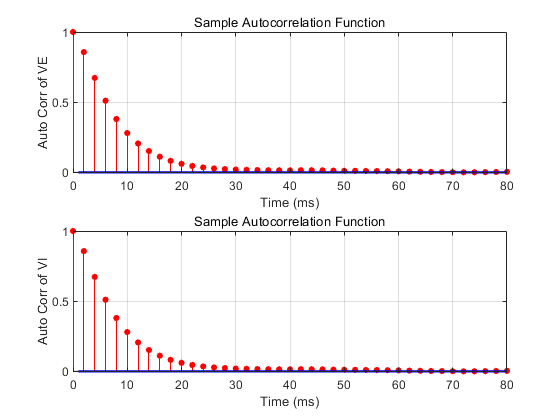

h = figure(1);
subplot 211
autocorr(VE_Sample,'NumLag',40,'NumSTD',3)
xticks(0:5:40)
xticklabels(0:5*Dt:40*Dt)
xlabel('Time (ms)'); ylabel('Auto Corr of VE')
subplot 212
autocorr(VI_Sample,'NumLag',40,'NumSTD',3)
xticks(0:5:40)
xticklabels(0:5*Dt:40*Dt)
xlabel('Time (ms)'); ylabel('Auto Corr of VI')

%set(gca,'YScale','log')

## Long-time Simulation + Var check

tic
ExpoType = 'All';
SimuTime = 1000*1e3; % in ms
TimeGrid = 0.1;
t_grid = 0:TimeGrid:SimuTime;
[VE_Single,SpE_Single] = MEanFieldEst_SingleCell('e', ExpoType, SimuTime, TimeGrid,...
                                         f_EnI_Single, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                         lambda_E,S_Elgn,rE_amb,S_amb,...
                                         lambda_I,S_Ilgn,rI_amb,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi);
[VI_Single,SpI_Single] = MEanFieldEst_SingleCell('i', ExpoType, SimuTime, TimeGrid,...
                                         f_EnI_Single, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                         lambda_E,S_Elgn,rE_amb,S_amb,...
                                         lambda_I,S_Ilgn,rI_amb,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi);
toc

历时 1.811899 秒。



BatchNumAll = logspace(log10(20),3,10);
VE_Var = zeros(size(BatchNumAll));
VI_Var = zeros(size(BatchNumAll));
SpE_Var = zeros(size(BatchNumAll));
SpI_Var = zeros(size(BatchNumAll));
for BatchInd = 1:length(BatchNumAll)
    BatchNum = BatchNumAll(BatchInd);
    Dt = floor(SimuTime/BatchNum)
    TSample_grid = 0:Dt:SimuTime;
    ScaleNum = floor(Dt/TimeGrid);
% Sample and average Vs by lengths
    VE_Sample = nanmean(reshape(VE_Single(1:ScaleNum*(length(TSample_grid)-1)),ScaleNum,length(TSample_grid)-1));
    VI_Sample = nanmean(reshape(VI_Single(1:ScaleNum*(length(TSample_grid)-1)),ScaleNum,length(TSample_grid)-1));
    SpE_Sample = zeros(1,length(TSample_grid)-1);
    SpI_Sample = zeros(1,length(TSample_grid)-1);
    for TSampleInd = 1:length(TSample_grid)-1
        SpE_Sample(TSampleInd)  = sum(SpE_Single >= TSample_grid(TSampleInd) & SpE_Single< TSample_grid(TSampleInd+1)) /(Dt/1e3);
        SpI_Sample(TSampleInd)  = sum(SpI_Single >= TSample_grid(TSampleInd) & SpI_Single< TSample_grid(TSampleInd+1)) /(Dt/1e3);
    end
    VE_Var(BatchInd) = var(VE_Sample);
    SpE_Var(BatchInd) = var(SpE_Sample);
    VI_Var(BatchInd) = var(VI_Sample);
    SpI_Var(BatchInd) = var(SpI_Sample);

end

Dt = 49999

Dt = 32373

Dt = 20961

Dt = 13572

Dt = 8787

Dt = 5689

Dt = 3684

Dt = 2385

Dt = 1544

Dt = 1000


figure(2)
subplot 211
hold on
plot(SimuTime./BatchNumAll,VE_Var)
plot(SimuTime./BatchNumAll,VI_Var)
ylabel('Variances')
legend('VE','VI')
subplot 212
hold on
plot(SimuTime./BatchNumAll,SpE_Var)
plot(SimuTime./BatchNumAll,SpI_Var)
%set(gca,'XScale','log','YScale','log')
xlabel('T/# of Batches')
ylabel('Variances')
legend('fE','fI')
